# LIDAR 

Laser Imaging Detection and Ranging is a sensor that emits beams of infrared laser light to mesure distance form sensort to objects. 

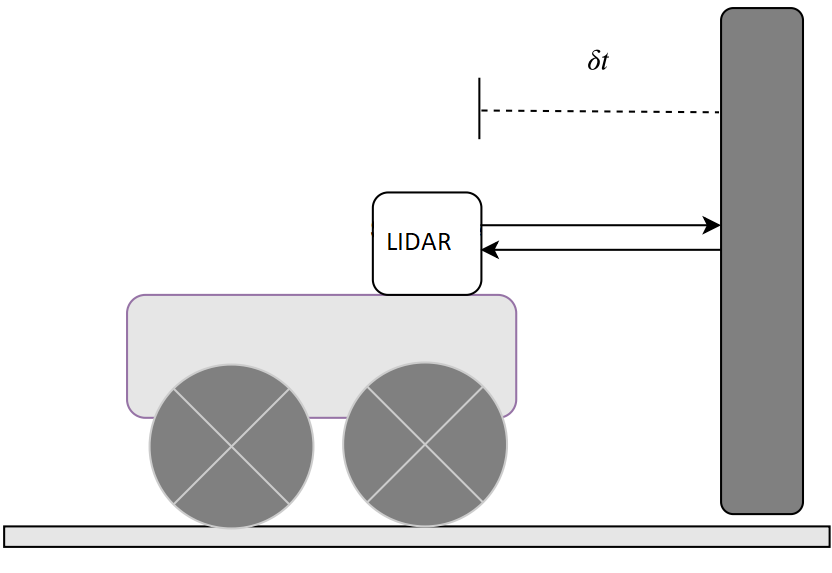

LIDAR emits infrared light in a specific direction then the light returns to LIDAR , the distance to an object is calculated based on the return time. The infrared light is emit in different directions to get a environment scan.

#### Create a LidarSensor Object and set parameters

lidar = LidarSensor;
lidar.sensorOffset = [0,0]; % Offset in [m] from robot center
lidar.scanAngles = linspace(-pi/2,pi/2,51); % define  how many lasers and the angle of each one.
lidar.maxRange = .7; %Max distance range [m]

Load a image as occupancy map.

map = generateMap(which('world1.png'), 0.1, 10);

Create a visualizer and assign  the  binaryOccupancyMap object.

robotRadius = .075;
viz = Visualizer2D;
viz.mapName = 'map';
viz.robotRadius = robotRadius;

Attach sensors to robot

attachLidarSensor(viz,lidar); 

In order to show the map and robot in action we define a similar code from previous lessons.

initPose = [ 0.25; 1.5; 0]; % [x ; y ; theta]    
R = 0.3; 
L = .12; 
mobileRobot = DifferentialDrive(R,L);

Velocity definition.

v = .2; % [m/s]
w = 0; % [rad/s]
bodyV = [v;0;w];    % Body velocities [vx;vy;w]  vy = 0 because the differential robot can not move in y axis.

### Execute simulation

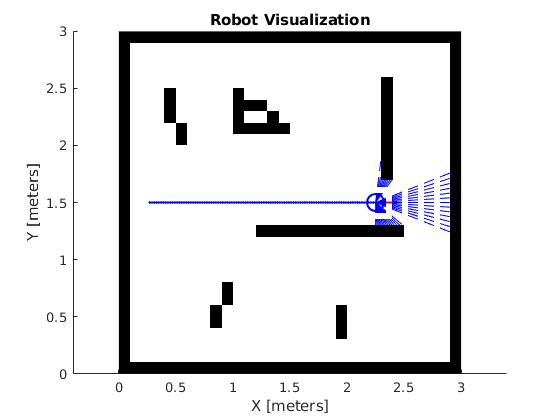

currentPose = initPose;    

[sampleTime,tVec,r] = simulTime(0.1,10); % Define Sample time, time array and rate control 
for idx = 2:numel(tVec) 
    
    % Convert from robot body to world
    vel =  bodyToWorld(bodyV,currentPose);  
   
    % Perform forward discrete integration step
    currentPose = currentPose + vel * sampleTime; 
    
    % Get the sensor readings from the real pose
    ranges = lidar(currentPose);
    
    % Update visualization
    viz(currentPose,ranges);
    
    %Wait for visualization rate
    waitfor(r);
    
end